                                            EXPERIMENT-7 IMAGE CONVOLUTION-1

NAME :- P.Sai Uttej

REG NO:- 19BCE7163

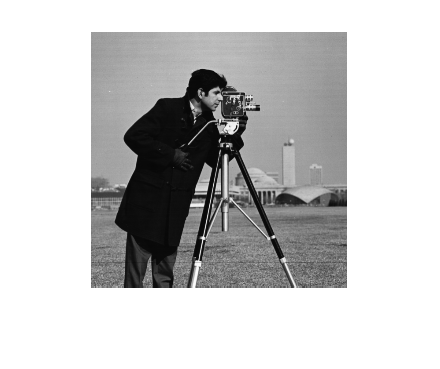


img=imread("cameraman.tif"); %reading cameraman image and loading into variable img
figure,imshow(img);          %displaying img's image

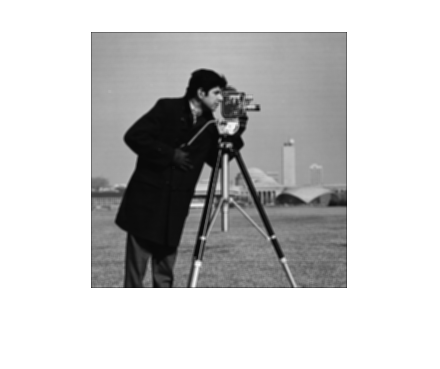

[m,n]=size(img);             %initializing the size of image into m and n variables
imgpad = zeros(258,258);     %assigning the imgpad to zeros 258 rows and 258 coloumns .
imgpad(2:257,2:257)=img;
mask=[1/9 1/9 1/9;1/9 1/9 1/9;1/9 1/9 1/9];% mask
new_img=convulution_user(imgpad,m,n,mask);
figure, imshow(uint8(new_img));      %displaying the output image.

**User defined function**

**convulution_user.m file**

function[op]= convulution_user(imgpad,m,n,mask)

    for i=1:m

    for j=1:n

        te=imgpad(i:i+2 , j:j+2).*mask;

        new_image(i,j)=sum(te,"all"); 

    end

end

end